# How many observations should I take? An application of the central limit theorem to human performance variables 

Author: Ross Wilkinson

## Introduction

The central limit theorem states that, under some conditions, the average of many samples (observations) of a random variable with finite mean and variance is itself a random variable—whose distribution converges to a normal distribution as the number of samples increases (Wikipedia).

Thus, we can assume that any measure of human performance will follow a normal distribution and that observations will regress toward a finite mean with a standard normal distribution of variance.

**Example**

We want to compare the maximal 1-s power output produced by a cyclist during a sprint on a traditional stationary ergometer under two different experimental conditions. But we are unsure of how many observations (number of sprints) we should take under each condition.

**Can we take one sample?**

We know that the subject's performance is likely to follow a normal distribution under each condition, so taking one sample (performing one sprint) under each condition has a ~68% chance of being within one standard deviation of their true mean and a ~95% chance of being within two standard deviations, and a ~99% chance of being within three standard deviations. But we have no idea of what the standard deviation is; is it 40 W, 100 W, etc.?

**Can we emprically determine how many observations are sufficient?**

The answer is yes. First, we need to verify that the subject's maximal power output follows a normal distribution; we can do this by taking as many observations as feasibly possible. Once we have an approximation of this distribution we can run simulations to test whether taking a certain number of samples is representative of the mean in the long run.

## Our experiment

We decide that it is feasible for a subject to perform 12 sprints, each seperated by 3 minutes of rest, in one testing session without introducing any dependent variables like fatigue. Once we have our results we will visualize the data, check for any linear trends, fit a distribution, then run our simulations to decide on the number of observations we should take.

## Our results

Here are the results from each of the 12 sprints in Watts.

maxPower = [1545; 1526; 1526; 1565; 1614; 1544; 1553;...
    1611; 1519; 1608; 1571; 1566];

## Visualize the data

**Histogram**

A histogram provides a quick visual insight into how a data set is distributed. The range of possible values is divided into intervals, or *bins*. Then a bar chart is created, where the height of each bar corresponds to how frequently values in that bin appear in the data.

Create a histogram of the results seperated into 3 bins.

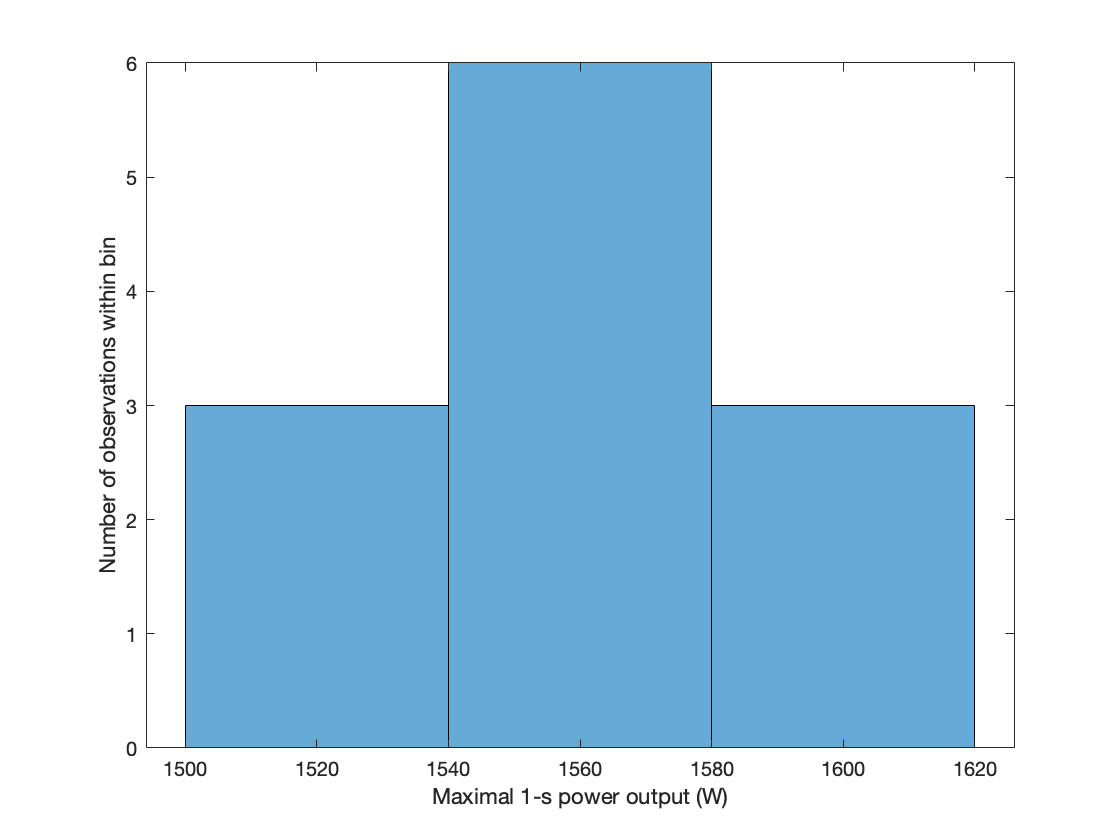

histogram(maxPower,3)
xlabel('Maximal 1-s power output (W)')
ylabel('Number of observations within bin')

**Scatter plots**

A scatter plot explores how two variables are related to each other. In this case how maximal power output is related to the trial number.

Create a scatter plot of the results across trials 1 to 12.

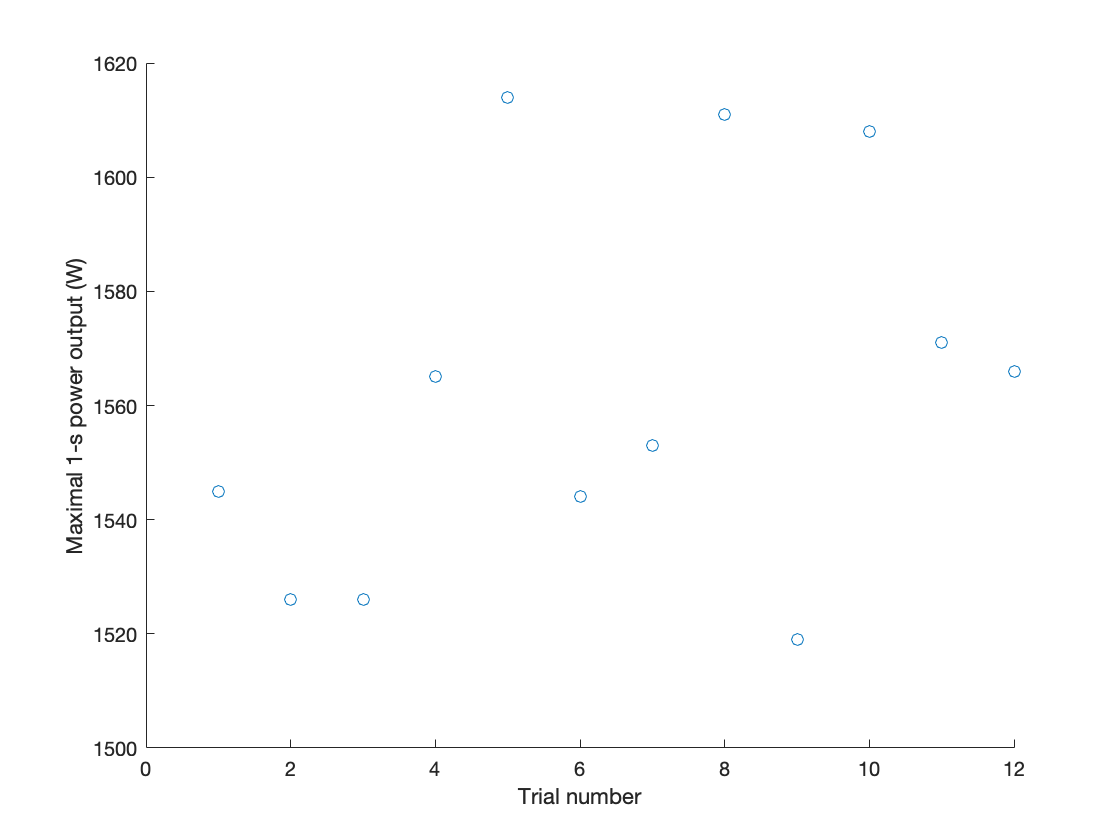

scatter(1:12,maxPower)
xlabel('Trial number')
ylabel('Maximal 1-s power output (W)')

**Box plots**

A box plot is another way to visualize the distribution of a data set. The central box represents the middle 50% of observations, with the red line at the median. The "whisker" lines show the extent of ~99% of the data. Remaining outliers are shown individually with red crosses. 

Create a box plot of the results.

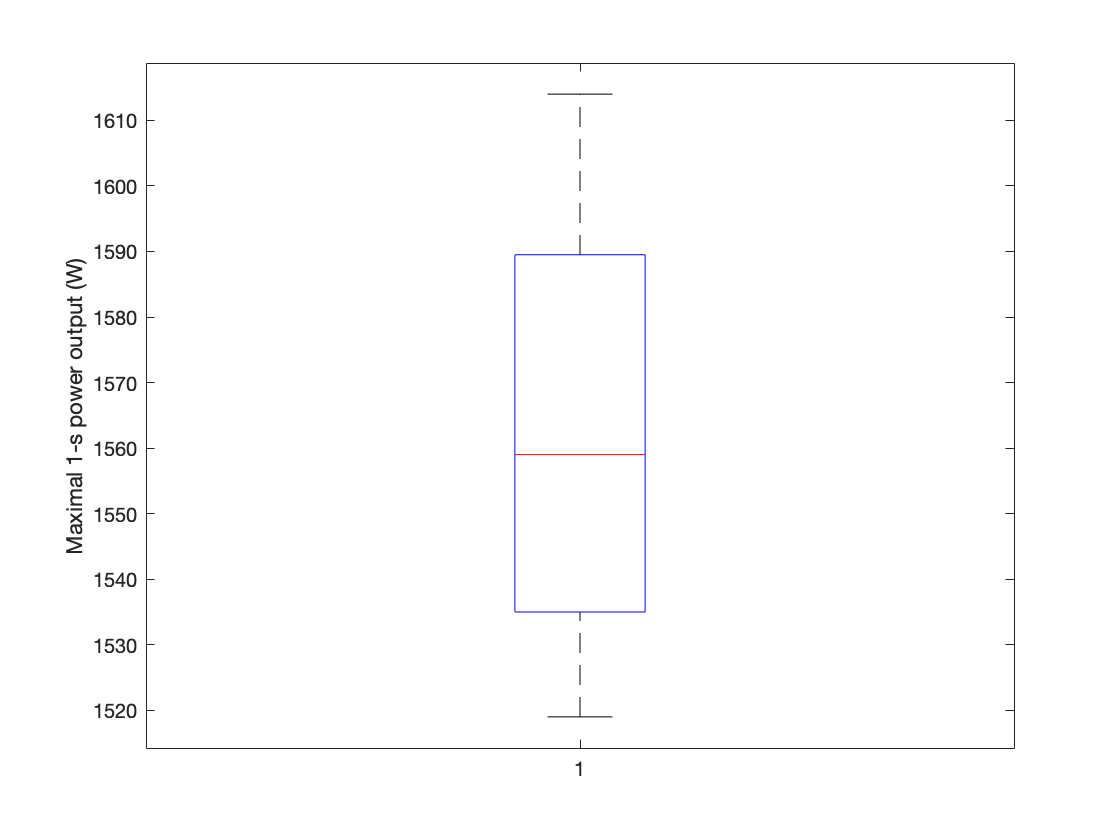

boxplot(maxPower)
ylabel('Maximal 1-s power output (W)')

## Measures of centrality and spread

Calculate the mean and median of the results

meanPwr = mean(maxPower)

meanPwr = 1.5623e+03

medPwr = median(maxPower)

medPwr = 1559

Calculate the standard deviation (STD) and interquartile range (IQR) of the results

stdPwr = std(maxPower)

stdPwr = 33.6569

iqrPwr = iqr(maxPower)

iqrPwr = 54.5000

The STD tells us that ~68% of the results will be within a ~68 W range from the mean of 1562 W, while the IQR tells us that 50% of the results will be within a ~55 W range from the median of 1559 W.

## Linear correlation

If we are 

Test whether there is a significant linear correlation between power output and the number of trials at the significance level 0.05.

nTrials = 1:12;
[r,p] = corrcoef(nTrials',maxPower)

r =     1.0000    0.3671
    0.3671    1.0000


p =     1.0000    0.2405
    0.2405    1.0000


This confirms that no significant linear correlation exists. Thus, taking a smaller number of samples will likely provide results that are normally distributed around the mean.

## Data distribution

Fit and plot a normal distribution then compare it to a fitted distribution.

x = 1300:1800;
pdfPwr = normpdf(x,meanPwr,stdPwr);
histogram(maxPower,3,"Normalization","pdf")
hold on
plot(x,pdfPwr,'k-','linewidth',2)

Fit a kernel distribution to the data

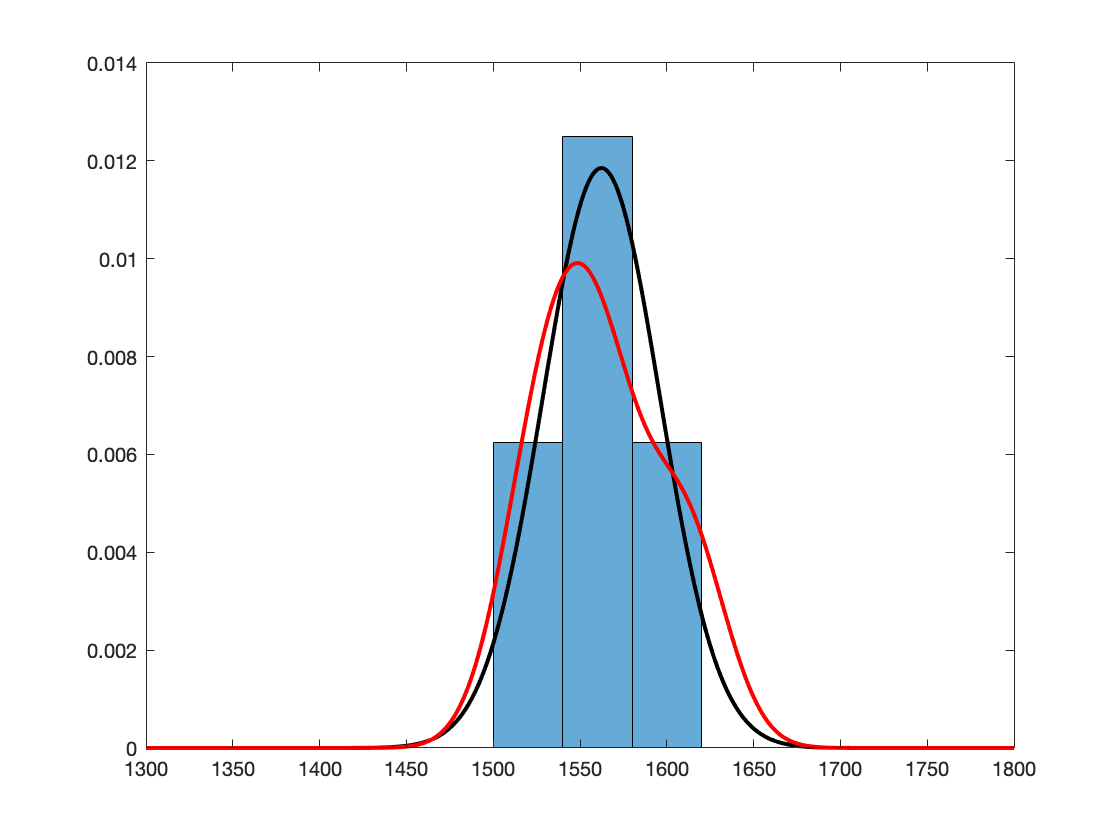

pd = fitdist(maxPower,'Kernel');
kerPwr = pdf(pd,x);
plot(x,kerPwr,'r-','linewidth',2)
hold off

## Compare distribution

Take random sample of 1000 observations from the fitted kernel distribution and compare it to a normal distribution.

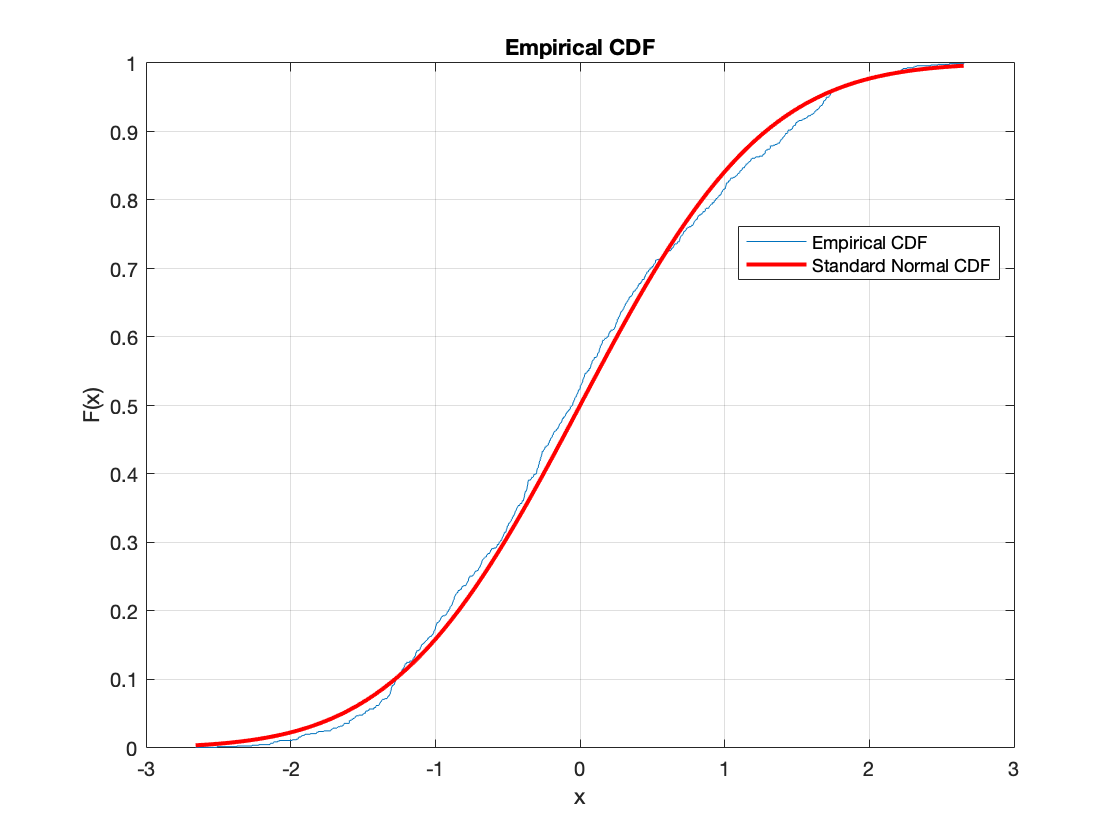

test1 = random(pd,1000,1);
mu = mean(test1);
sigma = std(test1);
zdist = (test1-mu) / sigma;

cdfplot(zdist)
hold on
x_values = linspace(min(zdist),max(zdist))';
plot(x_values,normcdf(x_values,0,1),'r-','linewidth',2)
legend('Empirical CDF','Standard Normal CDF','Location','best')
hold off

[h,p] = kstest(zdist);

## Run simulations to test if samples are significantly different

If the samples are similar then 10,000 t-test simulations should provide a uniform distribution of p-values.

Let's try two samples.

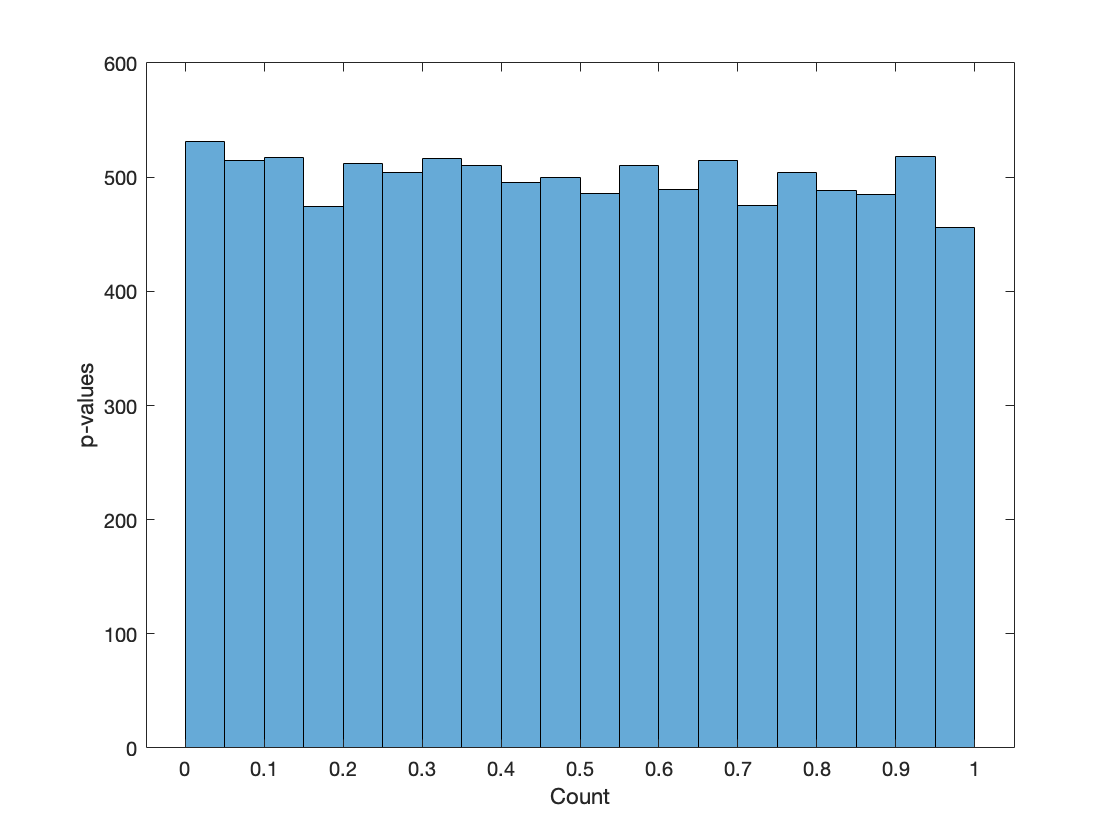

nSamples = 2;
for i = 1:10000
    x = random(pd,nSamples,1);
    y = random(pd,nSamples,1);
    [h,p,ci,stats] = ttest2(x,y);
    rho(i) = p;
end
histogram(rho,20)
xlabel('Count')
ylabel('p-values')

Test if p-value distribution is uniform

unipdf = makedist('uniform');
[h,p] = kstest(rho,'cdf',unipdf)

h = logical
   0


p = 0.2481

P-value is quite low. Let's try 3 samples.

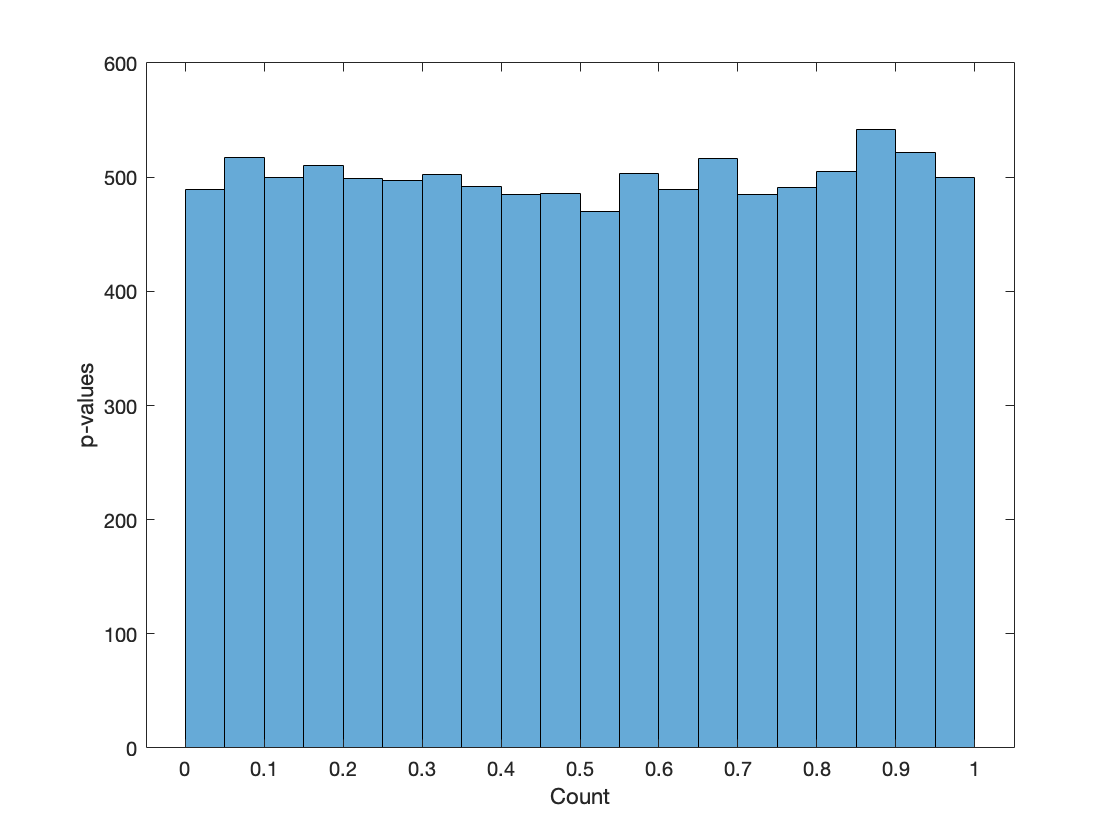

nSamples = 3;
for i = 1:10000
    x = random(pd,nSamples,1);
    y = random(pd,nSamples,1);
    [h,p,ci,stats] = ttest2(x,y);
    rho(i) = p;
end
histogram(rho,20)
xlabel('Count')
ylabel('p-values')

Test if p-value distribution is uniform

unipdf = makedist('uniform');
[h,p] = kstest(rho,'cdf',unipdf)

h = logical
   0


p = 0.4936

Much better! It appears that taking 3 samples is sufficient.